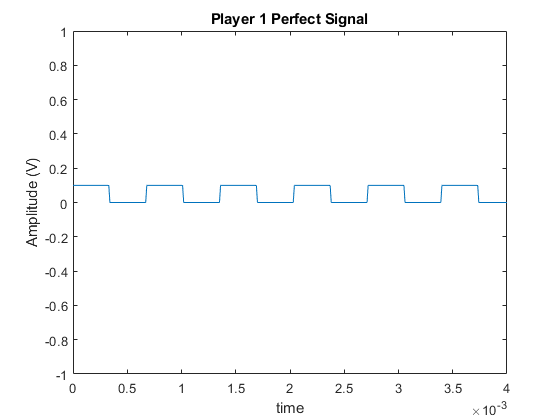

clear

FIR_b = importdata('FIR_B.txt');

IIR_a = importdata('a.txt');
IIR_b = importdata('b.txt');


%Load in optical noise
load light 

%we only want 200ms of data or 200e-3*100e3 = 20000 sample
t=linspace(0,.2,20000)';
y=y(1:20000);

%create the square wave signal
freq=1471;
y1=0.1*(0.5+0.5*square(2*pi*freq*t));

%Add square wave to the noise
y2=y+y1;

plot(t, y1);
xlim([0.000 0.004]);
ylim([-1 1]);
title('Player 1 Perfect Signal');
ylabel('Amplitude (V)');
xlabel('time');

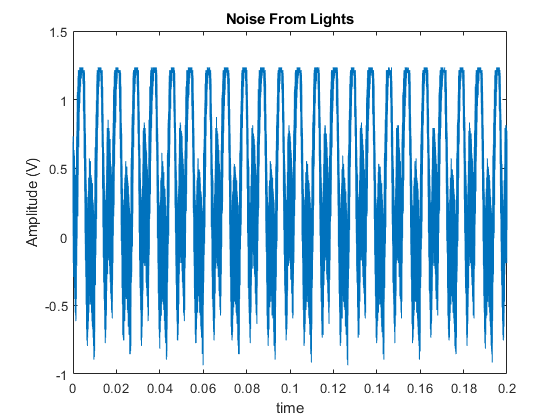



plot(t, y);
title('Noise From Lights');
ylabel('Amplitude (V)');
xlabel('time');

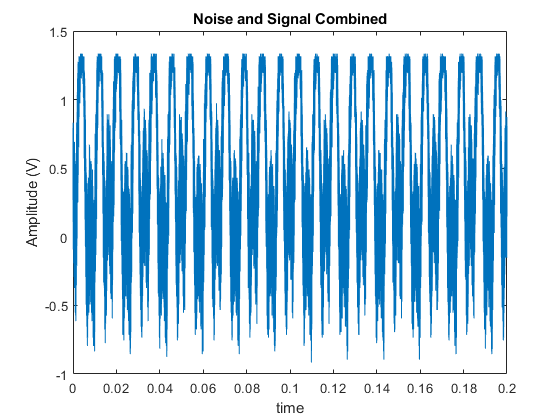


plot(t,y2);
title('Noise and Signal Combined');
ylabel('Amplitude (V)');
xlabel('time');

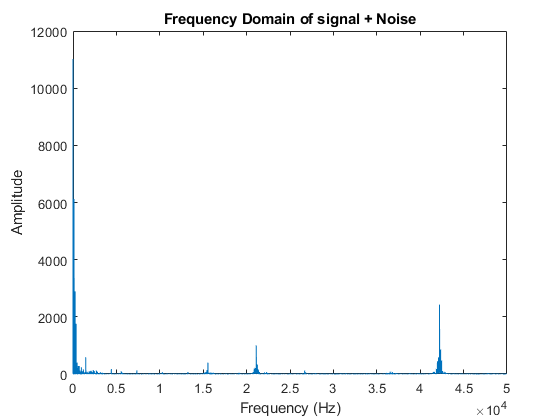



Y = fft(y2);

Fs=1/max(diff(t));
L=length(Y);
Y1=Y(1:L/2);            %we take the first half of the vector
f=linspace(0,Fs/2,L/2); %we create the frequency vector
plot(f, abs(Y1));

title('Frequency Domain of signal + Noise');
ylabel('Amplitude');
xlabel('Frequency (Hz)');

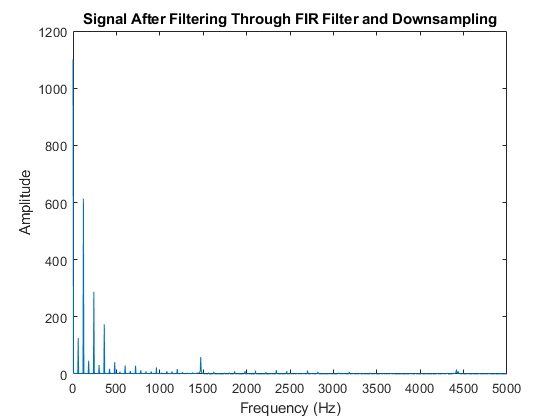










y_f = filter(FIR_b, 1, y2);
y_f_ds = y_f(1:10:length(y_f));
t_ds = t(1:10:length(t));

Y_f_ds = fft(y_f_ds);

Fs=1/max(diff(t_ds));
L=length(Y_f_ds);
Y1_f_ds=Y_f_ds(1:L/2);            %we take the first half of the vector
f=linspace(0,Fs/2,L/2); %we create the frequency vector
plot(f, abs(Y1_f_ds));
title('Signal After Filtering Through FIR Filter and Downsampling');
ylabel('Amplitude');
xlabel('Frequency (Hz)');

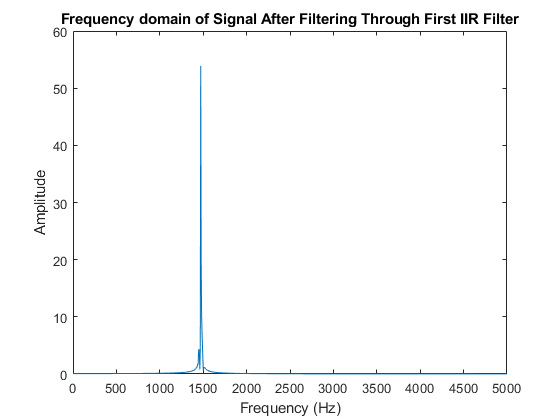










filter1 = filter(IIR_b(1, :), IIR_a(1, :), y_f_ds);
filter_fft = fft(filter1);

Fs=1/max(diff(t_ds));
L=length(filter_fft);
filter_fft_1=filter_fft(1:L/2);            %we take the first half of the vector
f=linspace(0,Fs/2,L/2); %we create the frequency vector
plot(f, abs(filter_fft_1));
ylim([0 60]);
title('Frequency domain of Signal After Filtering Through First IIR Filter');
ylabel('Amplitude');
xlabel('Frequency (Hz)');

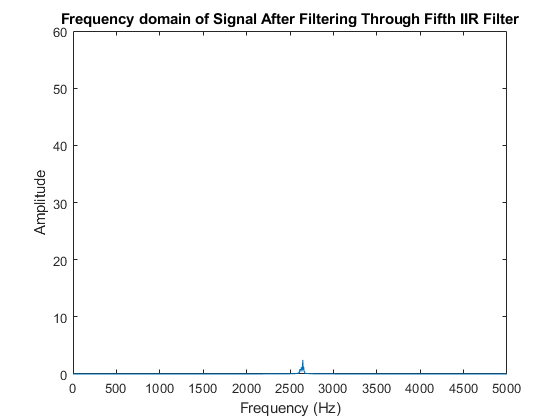





filter5 = filter(IIR_b(5, :), IIR_a(5, :), y_f_ds);
filter_fft5 = fft(filter5);

Fs=1/max(diff(t_ds));
L=length(filter_fft5);
filter_fft_1_5=filter_fft5(1:L/2);            %we take the first half of the vector
f=linspace(0,Fs/2,L/2); %we create the frequency vector
plot(f, abs(filter_fft_1_5));
ylim([0 60]);
title('Frequency domain of Signal After Filtering Through Fifth IIR Filter');
ylabel('Amplitude');
xlabel('Frequency (Hz)');

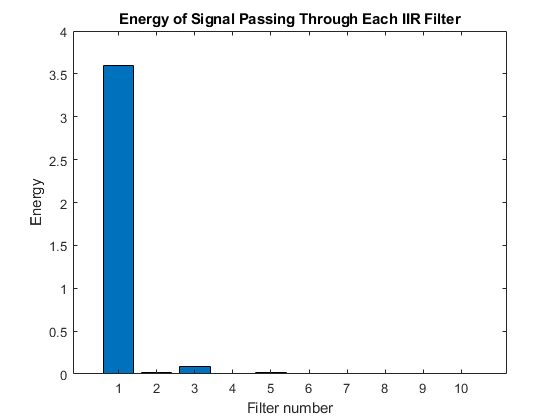





filter2 = filter(IIR_b(2, :), IIR_a(2, :), y_f_ds);
filter3 = filter(IIR_b(3, :), IIR_a(3, :), y_f_ds);
filter4 = filter(IIR_b(4, :), IIR_a(4, :), y_f_ds);
filter6 = filter(IIR_b(6, :), IIR_a(6, :), y_f_ds);
filter7 = filter(IIR_b(7, :), IIR_a(7, :), y_f_ds);
filter8 = filter(IIR_b(8, :), IIR_a(8, :), y_f_ds);
filter9 = filter(IIR_b(9, :), IIR_a(9, :), y_f_ds);
filter10 = filter(IIR_b(10, :), IIR_a(10, :), y_f_ds);


Fe = 1:10;

Fe(1) = sum(filter1 .^2);
Fe(2) = sum(filter2 .^2);
Fe(3) = sum(filter3 .^2);
Fe(4) = sum(filter4 .^2);
Fe(5) = sum(filter5 .^2);
Fe(6) = sum(filter6 .^2);
Fe(7) = sum(filter7 .^2);
Fe(8) = sum(filter8 .^2);
Fe(9) = sum(filter9 .^2);
Fe(10) = sum(filter10 .^2);

bar(Fe);

title('Energy of Signal Passing Through Each IIR Filter');
ylabel('Energy');
xlabel('Filter number');